## Riccati Differential Equation

#### Idle Mode:


$$\dot{\;\Omega \;} \left(t\right)=A\;\Omega \;\left(t\right)+\Omega \;\left(t\right)A^{T\;} +Q\;$$


Scaler case: $a\gets A,\;q\gets Q,\;\;\Omega {\;}_0 \gets \Omega \left(t_0 \right)$ 


$$\Omega \left(t\right)\;=\left(\Omega {\;}_{0\;} +\frac{q}{2a}\right)e^{2a\left(t-t_{0\;} \right)} -\frac{q}{2a}$$



$$J\left(t_{0\;} ,t_{0\;} +w\right)=\frac{1}{2a}\left(\Omega {\;}_{0\;} +\frac{q}{2a}\right)\left(e^{2\textrm{aw}} -1\right)-\frac{q}{2a\;}w$$


clear all; close all; clc;

a = 0.2628;
q = 0.8107;
t_0 = 5;
Omega_0 = 1

deltaT = 0.001;
periodT = 10;
Omega = Omega_0;
JArray = []; 
errorFrac = [];
OmegaArray = [];
for w = 0:deltaT:periodT % w = t-t_0
    Omega = Omega + deltaT*(2*a*Omega + q);
    OmegaAct = (Omega_0 + (q/(2*a)))*exp(2*a*w)-(q/(2*a));
    OmegaArray = [OmegaArray, OmegaAct];
    errorFrac = [errorFrac, (OmegaAct-Omega)*100/OmegaAct];
    
    % cost upto w
    J_w = (1/(2*a))*(Omega_0 + (q/(2*a)))*(exp(2*a*w)-1)-(q/(2*a))*w; 
    JArray = [JArray, J_w];
end
figure
plot(0:deltaT:periodT,errorFrac)
ylabel('Percentage Discretization Error')
xlabel('Time: w = t - t_0')
grid on
% Percentage discretization error grows linearly but is less than 1%

figure
plot(0:deltaT:periodT,OmegaArray)
ylabel('\Omega(t)')
xlabel('Time: w = t - t_0')
grid on

figure
plot(0:deltaT:periodT,JArray)
ylabel('J(t_0, t_0+w)')
xlabel('Time: w = t - t_0')
grid on

JArray1 = JArray;

#### Dwell Mode

$\dot{\;\Omega \;} \left(t\right)=A\;\Omega \;\left(t\right)+\Omega \;\left(t\right)A^{T\;} +Q\;-\Omega \;\left(t\right)\;G\;\Omega \left(t\right)$ with $G=H^T R^{-1} H$

Scaler case: $a\gets A,\;q\gets Q,\;\;g\gets G,\;\;\Omega {\;}_0 \gets \Omega \left(t_0 \right)$ 

$v_1 =\frac{1}{q}\left(-a+\sqrt{a^2 +\textrm{qg}}\right)$ and $v_2 =\frac{1}{q}\left(-a-\sqrt{a^2 +\textrm{qg}}\right)$ and $\lambda =2\sqrt{a^2 +\textrm{qg}}$


$$\Omega \left(t\right)\;=\frac{\left(v_2 \;\Omega {\;}_0 -1\right)\;+\;\left(-v_1 \;\Omega_0 +1\right)e^{-\lambda \;\left(t-t_0 \right)} }{v_1 \left(v_2 \;\Omega {\;}_0 -1\right)+v_2 \left(-v_1 \;\Omega_0 +1\right)e^{-\lambda \;\left(t-t_0 \right)} \;}\;$$



$$J\left(t_{0\;} ,t_{0\;} +w\right)=\frac{1}{g}\ln \left(v_1 \left(v_2 \;\Omega {\;}_0 -1\right)+v_2 \left(-v_1 \;\Omega_0 +1\right)e^{-\lambda \;w} \right)\;+\;\frac{w}{v_1 }\;-\;\frac{1}{g}\ln \left(v_2 -v_1 \right)$$


% clear all; close all; clc;

a = 0.2628;
q = 0.8107;
r = 5.7044;
h = 1;
g = h'*r^(-1)*h;

v_1 = (-a+sqrt(a^2+q*g))/q
v_2 = (-a-sqrt(a^2+q*g))/q
lambda = 2*sqrt(a^2+q*g)
Omega_ss = 1/v_1

t_0 = 5;
Omega_0 = 100

c_1 = v_2*Omega_0 - 1
c_2 = -v_1*Omega_0 + 1
c_3 = v_1*c_1
c_4 = v_2*c_2

e = 0.05; % get 95% closer to Omega_ss
t_e = t_0 + (-1/lambda)*log((-e*v_1*c_1)/((v_1+(1-e)*v_2)*c_2))
% t_e = t_0 + (-1/lambda)*log((e*v_1*c_1)/((v_1+(1+e)*v_2)*c_2))

deltaT = 0.001;
periodT = 10;
Omega = Omega_0;
JArray = []; 
errorFrac = [];
OmegaArray = [];
for w = 0:deltaT:periodT % w = t-t_0
    Omega = Omega + deltaT*(2*Omega*a + q - Omega^2*g);
    OmegaAct = (c_1 + c_2*exp(-lambda*w))/(c_3 + c_4*exp(-lambda*w));
    OmegaArray = [OmegaArray, OmegaAct];
    errorFrac = [errorFrac, (OmegaAct-Omega)*100/OmegaAct];
    
%     % cost upto w
    J_w = (1/g)*log(c_3+c_4*exp(-lambda*w)) + (1/v_1)*w - (1/g)*log(v_2-v_1);
    JArray = [JArray, J_w];
end
figure
plot(0:deltaT:periodT,errorFrac)
ylabel('Percentage Discretization Error')
xlabel('Time: w = t - t_0')
grid on
% Percentage discretization error grows linearly but is less than 1%


figure
plot(0:deltaT:periodT,OmegaArray)
ylabel('\Omega(t)')
xlabel('Time: w = t - t_0')
grid on

figure
plot(0:deltaT:periodT,JArray)
ylabel('J(t_0, t_0+w)')
xlabel('Time: w = t - t_0')
grid on

JArray2 = JArray;

### Case 2: 

figure
plot(0:deltaT:periodT,(JArray1+JArray2)./(0:deltaT:periodT))
% plot(0:deltaT:periodT,(JArray1+JArray2))
ylabel('J_T(t_0, t_0+w)')
xlabel('Time: w = t - t_0')
grid on

Next target solution: RHCP2

syms u positive
syms lambda_1 lambda_2 positive
% with no external neighbors
% Agent 1 finished dwelling at t = 0.539 at taregt 1
% No Solution! i=1, j=2, cost=2.6809
H = 0.2318*u + 5.6831*exp(0.5256*u + 0.19392) + 5.2993*log(0.26685*exp(-0.63111*u) + 0.93361) - 6.8784
J = (0.2318*u + 5.6831*exp(0.5256*u + 0.19392) + 5.2993*log(0.26685*exp(-0.63111*u) + 0.93361) - 6.8784)/(u + 0.36896)
figure
ezplot(H,[0,10])
figure
ezplot(J,[0,10])

Horizon = 10;
rho = 0.36896;
Hamil = J+lambda_1*(-u)+lambda_2*(u-(Horizon-rho));
eqn1 = diff(Hamil,u)==0
eqn2 = lambda_1*(-u)==0
eqn3 = lambda_2*(u-(Horizon-rho))==0
[uSol,L1,L2] = vpasolve([eqn1,eqn2,eqn3],[u,lambda_1,lambda_2],[0,Horizon;0 inf;0 inf])

% DDJ = vpa(simplify(diff(diff(J,u),u)),5)
% ezplot(DDJ,[0,10])

% Agent 2 finished dwelling at t = 3.298 at taregt 2
% Solution Found: i=2, j=1, cost=14.3485, u=0.063446
H = 397.2*exp(0.038474*u + 0.014195) - 9.5439*u + 5.7044*log(3.2513 - 2.1175*exp(-0.91909*u)) - 398.35
J = -(1.0*(9.5439*u - 397.2*exp(0.038474*u + 0.014195) - 5.7044*log(3.2513 - 2.1175*exp(-0.91909*u)) + 398.35))/(u + 0.36896)
figure
ezplot(H,[0,100])
figure
ezplot(J,[0,10])

Hamil = J+lambda_1*(-u)+lambda_2*(u-(Horizon-rho));
eqn1 = diff(Hamil,u)==0
eqn2 = lambda_1*(-u)==0
eqn3 = lambda_2*(u-(Horizon-rho))==0
[uSol,L1,L2] = vpasolve([eqn1,eqn2,eqn3],[u,lambda_1,lambda_2],[0,Horizon;0 inf;0 inf])


% with all the neighbors
% Agent 2 finished dwelling at t = 3.378 at taregt 3
% 
H = 33.301*exp(0.57729*u + 0.19643) - 35.155*u + 420.02*exp(0.038474*u + 0.013091) + 44.83*exp(0.4406*u + 0.14992) + 364.86*exp(0.028117*u + 0.0095669) + 121.63*exp(0.1178*u + 0.040081) + 5.7044*log(3.3426 - 2.2088*exp(-0.91909*u)) - 994.3
J = (33.301*exp(0.57729*u + 0.19643) - 35.155*u + 420.02*exp(0.038474*u + 0.013091) + 44.83*exp(0.4406*u + 0.14992) + 364.86*exp(0.028117*u + 0.0095669) + 121.63*exp(0.1178*u + 0.040081) + 5.7044*log(3.3426 - 2.2088*exp(-0.91909*u)) - 994.3)/(u + 0.34026)
figure
ezplot(H,[0,10])
figure
ezplot(J,[0,10])

syms u positive
%  Agent 1 finished dwelling at t = 0.001 at taregt 1
J = (4.41361e+32*exp(0.5256*u) - 2.29096e+33*u + 9.66704e+32*exp(0.440604*u) + 2.72006e+34*exp(0.0281169*u) + 1.04383e+33*exp(0.466657*u) + 8.91441e+33*exp(0.117795*u) - 3.83455e+34)/(1.43939e+32*u + 4.29933e+32*log(0.374903*exp(-0.631114*u) + 0.825556) - 7.85505e+31)
tic
uSol = vpasolve(diff(J,u)==0,u,[0,10])
toc

J = vpa(J,4)
tic
uSol = vpasolve(diff(J,u)==0,u,[0,10])
toc

Jt = vpa(taylor(J,u,1),5)
tic
uSol = vpasolve(diff(Jt,u)==0,u,[0,10])
toc


temp = log(0.374903*exp(-0.631114*u) + 0.825556)
temp2 = vpa(taylor(temp,u,0),5)
figure
ezplot(temp,[0,2])
hold on
ezplot(temp2,[0,2])

syms t positive
% 
% temp2 = vpa(simplify(subs(temp,u,log(t))),5)
% Jt = vpa(taylor(temp,u),5)
% 

figure
ezplot(J,[0,10])
hold on
ezplot(Jt,[0,2])

figure
ezplot(diff(J,u),[0,10])

figure
ezplot(diff(diff(J,u),u),[0,10])

% looking into active and inactive parts of the local objective function

% Agent 1 finished dwelling at t = 0.001 at taregt 1
% Solution Found: i=1, j=2, cost=-0.052986, u=0.63004
syms u positive
A = (1997558976658343*u)/1125899906842624 + (1491631261260099*log(abs((6753652402088849*exp(-(2842286668281031*u)/4503599627370496))/18014398509481984 + 7435944753897113/9007199254740992)))/281474976710656 - 8720852316336059/9007199254740992;
B = (1850792489003731*exp((8488050406509199*u)/72057594037927936 + 56416124694879172517639103826931/1298074214633706907132624082305024))/17592186044416 - (127173751334885961*u)/4503599627370496 + (2522690879762497*exp((4734183539382577*u)/9007199254740992 + 31465916917910144940727169118413/162259276829213363391578010288128))/562949953421312 + (2918656556123357*exp((1013017794093903*u)/36028797018963968 + 6733058294034899873251666102707/649037107316853453566312041152512))/8796093022208 + (5701421874600487*exp((1984302092869915*u)/4503599627370496 + 13188733447884657501290123261135/81129638414606681695789005144064))/562949953421312 + (6097418832529433*exp((4203268881070557*u)/9007199254740992 + 27937174022757119019552810633033/162259276829213363391578010288128))/562949953421312 - 38345545316978249080093261826983557/81129638414606681695789005144064;
A = vpa(taylor(A,u),5)
B = vpa(taylor(B,u),5)
J = simplifyFraction(A/(A+B))
figure
ezplot(J,[0,10])
Adot = vpa(simplify(diff(A,u)),5)
Bdot = vpa(simplify(diff(B,u)),5)
vpasolve(A*Bdot==B*Adot,u,[0,10])
Addot = vpa(simplify(diff(Adot,u)),5)
Bddot = vpa(simplify(diff(Bdot,u)),5)
C = vpa(simplify(B*Addot - A*Bddot),5)
figure
ezplot(C,[0,10])


% with stabel A
% Agent 1 finished dwelling at t = 0.001 at taregt 1
% Solution Found: i=1, j=2, cost=-0.068569, u=0.63004
 
A = (1768001018599217*u)/1125899906842624 + (1491631261260099*log(abs((2775170073191597*exp(-(2842286668281031*u)/4503599627370496))/9007199254740992 + 8037600881749939/9007199254740992)))/281474976710656 - 8720852316336059/9007199254740992;
B = (127173751334885961*u)/4503599627370496 + (5840097815520821*exp(- (8488050406509199*u)/72057594037927936 - 56416124694879172517639103826931/1298074214633706907132624082305024))/70368744177664 + (1566262512155597*exp(- (4734183539382577*u)/9007199254740992 - 31465916917910144940727169118413/162259276829213363391578010288128))/1125899906842624 + (1379353855740199*exp(- (1013017794093903*u)/36028797018963968 - 6733058294034899873251666102707/649037107316853453566312041152512))/4398046511104 + (1105001771684693*exp(- (1984302092869915*u)/4503599627370496 - 13188733447884657501290123261135/81129638414606681695789005144064))/281474976710656 + (8852661329363497*exp(- (4203268881070557*u)/9007199254740992 - 27937174022757119019552810633033/162259276829213363391578010288128))/2251799813685248 - 32064258978344405996488115146094971/81129638414606681695789005144064;
A = vpa(A,5)
B = vpa(B,5)
Adot = vpa(simplify(diff(A,u)),5)
Bdot = vpa(simplify(diff(B,u)),5)
vpasolve(A*Bdot==B*Adot,u,[0,10])
Addot = vpa(simplify(diff(Adot,u)),5)
Bddot = vpa(simplify(diff(Bdot,u)),5)
C = vpa(simplify(B*Addot - A*Bddot),5)
figure
ezplot(C,[0,10])


% No sol case
% Target 7 observation error.
% Agent 1 finished dwelling at t = 0.572 at taregt 7
% No Solution! i=7, j=1, cost=0
 
A = (7399254277060949*u)/2251799813685248 + (3731237466964757*log(6869291714810381/4651212283438094 - (4436158862744573*exp(-(6330999558834973*u)/4503599627370496))/9302424566876188))/1125899906842624
B = (7156330095647461*exp((4734183539382577*u)/9007199254740992 + 13459163478556785927400301454525/40564819207303340847894502572032))/1125899906842624 - (147847481859838377*u)/4503599627370496 + (8006020572883345*exp((8488050406509199*u)/72057594037927936 + 24131311573597528594117024668675/324518553658426726783156020576256))/70368744177664 + (8309026921958541*exp((4203268881070557*u)/9007199254740992 + 11949786598691346970612117628025/40564819207303340847894502572032))/562949953421312 + (6657017411876817*exp((5544732997894649*u)/144115188075855872 + 15763534988198854047781119389925/649037107316853453566312041152512))/17592186044416 + (955185273664295*exp((1984302092869915*u)/4503599627370496 + 5641320417049491205370810937375/20282409603651670423947251286016))/70368744177664 - 11052311051480947725960039406803157/20282409603651670423947251286016

% A = vpa(taylor(A,u),5)
% B = vpa(taylor(B,u),5)
J = simplifyFraction(A/(A+B))
figure
ezplot(J,[0,10])
Adot = vpa(simplify(diff(A,u)),5)
Bdot = vpa(simplify(diff(B,u)),5)
tic
uSol = vpasolve(A*Bdot==B*Adot,u,[0,10])
toc
Addot = vpa(simplify(diff(Adot,u)),5)
Bddot = vpa(simplify(diff(Bdot,u)),5)
C = vpa(simplify(B*Addot - A*Bddot),5)
figure
ezplot(C,[0,10])

figure
ezplot(J,[0,2])


% gradient descent

tic
JFun = matlabFunction(J);
JFun(double(uSol))
DJFun = matlabFunction(diff(J,u));

u_ik = 0.5;
Jval = JFun(u_ik);
beta = 0.1;
for k = 1:1:100000
    grad = DJFun(u_ik);
    u_ik = u_ik + beta*grad;
    if u_ik<0
        u_ik =0;
    end
    
    Jval2 = JFun(u_ik);
    if abs(Jval-Jval2)<0.0000000001
        k
        u_ik
        Jval2
        break
    end
    Jval = Jval2;
end
u_ik
toc




syms u_i u_j
A = 4.12051*u_i + 1.77419*u_j + 5.29934*log(4.243*exp(0.0384743*u_i + 0.0141954) - 0.833015*exp(-0.631114*u_j)*(5.09354*exp(0.0384743*u_i + 0.0141954) - 5.54146) - 3.61612) + 5.70437*log(0.631095*exp(-0.919086*u_i) + 0.368905)
B = 368.835*exp(0.0384743*u_i + 0.0141954) - 28.2382*u_j - 40.3602*u_i + 10.1233*exp(0.440604*u_i + 0.440604*u_j + 0.162564) + 331.804*exp(0.0281169*u_i + 0.0281169*u_j + 0.0103739) + 10.8261*exp(0.466657*u_i + 0.466657*u_j + 0.172176) + 105.193*exp(0.117795*u_i + 0.117795*u_j + 0.0434614) + (4.93038e-32*(8.23216e+47*exp(0.919086*u_i) + 1.04473e+47)*(exp(0.5256*u_j + 0.193924) - 1.0))/(3.76713e+15*exp(0.919086*u_i) + 6.44451e+15) - 842.241
J = A/(B+A)
figure
J_i = subs(J,u_j,0)
J_j = subs(J,u_i,0)
figure
ezplot(J_i,[0,10])
figure
ezplot(J_j,[0,10])

DJ_i = diff(J,u_i);
DJ_j = diff(J,u_j);
tic
% vpasolve([DJ_i==0,DJ_j==0],[u_i,u_j],[0,10;0,10])
toc

% grad descent
tic
JFun = matlabFunction(J);
DJ_iFun = matlabFunction(DJ_i);
DJ_jFun = matlabFunction(DJ_j);

u_ik = 1; u_jk = 1;
Jval = JFun(u_ik,u_jk)
beta = 0.1;
for k = 1:1:10000
    grad_i = DJ_iFun(u_ik,u_jk);
    u_ik = u_ik + beta*grad_i;
    if u_ik<0
        u_ik =0;
    end
    
    grad_j = DJ_jFun(u_ik,u_jk);
    u_jk = u_jk + beta*grad_j;
    if u_jk<0
        u_jk =0;
    end
    
    Jval2 = JFun(u_ik,u_jk);
    if abs(Jval-Jval2)<0.0000001
        u_ik
        u_jk
        Jval2
        k
        break
    end
    Jval = Jval2;
end
u_ik
u_jk
Jval 
toc

Plotting J_H(u_i,u_j) : For convexity check

syms u_i u_j positive
A = 4.12051*u_i + 1.77419*u_j + 5.29934*log(4.243*exp(0.0384743*u_i + 0.0141954) - 0.833015*exp(-0.631114*u_j)*(5.09354*exp(0.0384743*u_i + 0.0141954) - 5.54146) - 3.61612) + 5.70437*log(0.631095*exp(-0.919086*u_i) + 0.368905)
B = 368.835*exp(0.0384743*u_i + 0.0141954) - 28.2382*u_j - 40.3602*u_i + 10.1233*exp(0.440604*u_i + 0.440604*u_j + 0.162564) + 331.804*exp(0.0281169*u_i + 0.0281169*u_j + 0.0103739) + 10.8261*exp(0.466657*u_i + 0.466657*u_j + 0.172176) + 105.193*exp(0.117795*u_i + 0.117795*u_j + 0.0434614) + (4.93038e-32*(8.23216e+47*exp(0.919086*u_i) + 1.04473e+47)*(exp(0.5256*u_j + 0.193924) - 1.0))/(3.76713e+15*exp(0.919086*u_i) + 6.44451e+15) - 842.241
J = -A/(B+A)
fsurf(J,[0,10])
xlabel('u_i')
ylabel('u_j')
zlabel('J_H(u_i,u_j)')

DAii = vpa(simplify(diff(A,u_i,2)),20)
DBii = vpa(simplify(diff(B,u_i,2)),20)
fsurf(DAii,[0,10])
fsurf(DBii,[0,10])
fsurf(A*DBii-B*DAii,[0,10])

DAjj = vpa(simplify(diff(A,u_j,2)),20)
DBjj = vpa(simplify(diff(B,u_j,2)),20)
fsurf(DAjj,[0,10])
fsurf(DBjj,[0,10])
fsurf(A*DBjj-B*DAjj,[0,10])

DAij = vpa(simplify(diff(A,u_i,u_j)),20)
DBij = vpa(simplify(diff(B,u_i,u_j)),20)
fsurf(DAij,[0,10])
fsurf(DBij,[0,10])
delta = vpa((A*DBii-B*DAii)*(A*DBjj-B*DAjj) - (A*DBij-B*DAij)^2,20)
fsurf(delta,[0,10])


syms u_i u_j positive
A = 4.12051*u_i + 1.77419*u_j + 5.29934*log(4.243*exp(0.0384743*u_i + 0.0141954) - 0.833015*exp(-0.631114*u_j)*(5.09354*exp(0.0384743*u_i + 0.0141954) - 5.54146) - 3.61612) + 5.70437*log(0.631095*exp(-0.919086*u_i) + 0.368905)

$$A = \begin{array}{l} \frac{4639281825144101\,u_{i}}{1125899906842624}+\frac{1997560355721115\,u_{j}}{1125899906842624}+\frac{6422549651595859\,\log\left(\frac{2842199206835383\,{\mathrm{e}}^{-\frac{8278390734242879\,u_{i}}{9007199254740992}}}{4503599627370496}+\frac{6645601682140451}{18014398509481984}\right)}{1125899906842624}+\frac{5966526412327391\,\log\left(\frac{4243\,\sigma_{1}}{1000}-\frac{7503132087188067\,{\mathrm{e}}^{-\frac{2842284775228303\,u_{j}}{4503599627370496}}\,\left(\frac{5734816211499179\,\sigma_{1}}{1125899906842624}-\frac{6239129297772127}{1125899906842624}\right)}{9007199254740992}-\frac{90403}{25000}\right)}{1125899906842624}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{\frac{2772365490293451\,u_{i}}{72057594037927936}+\frac{4091545481624009}{288230376151711744}} \end{array}$$

B = 368.835*exp(0.0384743*u_i + 0.0141954) - 28.2382*u_j - 40.3602*u_i + 10.1233*exp(0.440604*u_i + 0.440604*u_j + 0.162564) + 331.804*exp(0.0281169*u_i + 0.0281169*u_j + 0.0103739) + 10.8261*exp(0.466657*u_i + 0.466657*u_j + 0.172176) + 105.193*exp(0.117795*u_i + 0.117795*u_j + 0.0434614) + (4.93038e-32*(8.23216e+47*exp(0.919086*u_i) + 1.04473e+47)*(exp(0.5256*u_j + 0.193924) - 1.0))/(3.76713e+15*exp(0.919086*u_i) + 6.44451e+15) - 842.241

$$B = \begin{array}{l} \frac{7402299306281009\,{\mathrm{e}}^{\frac{8488024289697721\,u_{i}}{72057594037927936}+\frac{8488024289697721\,u_{j}}{72057594037927936}+\frac{3131723917520001}{72057594037927936}}}{70368744177664}-\frac{3974173343675423\,u_{j}}{140737488355328}-\frac{5680193177518709\,u_{i}}{140737488355328}+\frac{356181953966873\,{\mathrm{e}}^{\frac{992152005108975\,u_{i}}{2251799813685248}+\frac{992152005108975\,u_{j}}{2251799813685248}+\frac{2928492679295429}{18014398509481984}}}{35184372088832}+\frac{73767\,{\mathrm{e}}^{\frac{2772365490293451\,u_{i}}{72057594037927936}+\frac{4091545481624009}{288230376151711744}}}{200}+\frac{82951\,{\mathrm{e}}^{\frac{253254520725627\,u_{i}}{9007199254740992}+\frac{253254520725627\,u_{j}}{9007199254740992}+\frac{5980146198320485}{576460752303423488}}}{250}+\frac{3047276245367233\,{\mathrm{e}}^{\frac{4203272582619667\,u_{i}}{9007199254740992}+\frac{4203272582619667\,u_{j}}{9007199254740992}+\frac{10761}{62500}}}{281474976710656}+\frac{\left({\mathrm{e}}^{\frac{657\,u_{j}}{1250}+\frac{6986848433105569}{36028797018963968}}-1\right)\,\left(\frac{45697661776677230516074615210485\,\sigma_{1}}{1125899906842624}+\frac{46395325832294806819119341176833}{9007199254740992}\right)}{3767130000000000\,\sigma_{1}+6444510000000000}-\frac{463026886444843}{549755813888}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{\frac{8278390734242879\,u_{i}}{9007199254740992}} \end{array}$$

J = -A/(B+A)

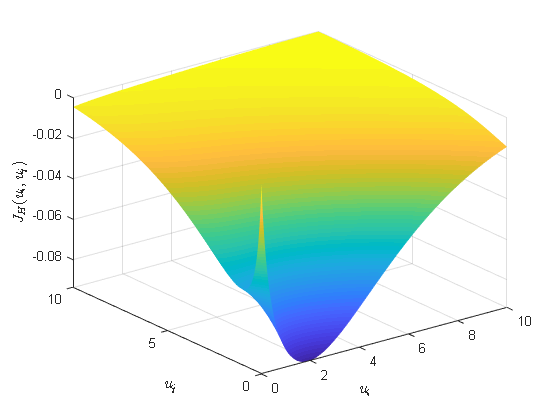

fsurf(J,[0,10],'EdgeColor','none')
xlabel('$u_i$','Interpreter',"latex")
ylabel('$u_j$','Interpreter',"latex")
zlabel('$J_H(u_i,u_j)$','Interpreter',"latex")

% Agent 1 finished dwelling at t = 1.069 at taregt 4
% Solution Found: i=5, j=1, cost=-0.1338, u_i=0.89288, u_j=0.81167
syms u_i u_j positive
A = 3.28593*u_i + 4.12051*u_j + 5.70437*log(0.787541*exp(0.5256*u_i + 0.319147) - 0.882052*exp(-0.919086*u_j)*(0.892851*exp(0.5256*u_i + 0.319147) - 1.22456) - 0.0801285) + 3.314*log(0.135276*exp(-1.40576*u_i) + 0.864724)
B = 7.85564*exp(0.5256*u_i + 0.319147) - 30.5494*u_j - 29.7339*u_i + 384.321*exp(0.0384743*u_i + 0.0384743*u_j + 0.0233618) + 13.2416*exp(0.466657*u_i + 0.466657*u_j + 0.283357) + 119.309*exp(0.117795*u_i + 0.117795*u_j + 0.071526) + (1.97215e-31*(7.97509e+47*exp(1.40576*u_i) + 2.17752e+46)*(exp(0.577292*u_j + 0.350535) - 1.0))/(1.60881e+16*exp(1.40576*u_i) + 2.51678e+15) - 544.213
J = -A/(B+A);
fsurf(J,[0,10],'EdgeColor','none')
xlabel('$u_i$','Interpreter',"latex")
ylabel('$u_j$','Interpreter',"latex")
zlabel('$J_H(u_i,u_j)$','Interpreter',"latex")

% Solution Found: i=1, j=4, cost=-0.20048, u_i=0, u_j=0.78714
syms u_i u_j positive
A = 4.12051*u_i + 3.00382*u_j + 2.99919*log(1.09636*exp(0.466657*u_i + 0.100344) - 1.04574*exp(-1.53643*u_j)*(1.04841*exp(0.466657*u_i + 0.100344) - 1.33785) - 0.399039) + 5.70437*log(0.631095*exp(-0.919086*u_i) + 0.368905)
B = 368.835*exp(0.0384743*u_i + 0.0384743*u_j + 0.00827306) - 38.4596*u_j - 40.3602*u_i + 10.8261*exp(0.466657*u_i + 0.100344) + 10.1233*exp(0.440604*u_i + 0.440604*u_j + 0.0947421) + 331.804*exp(0.0281169*u_i + 0.0281169*u_j + 0.00604592) + 105.193*exp(0.117795*u_i + 0.117795*u_j + 0.0253293) + (4.93038e-32*(8.23216e+47*exp(0.919086*u_i) + 1.04473e+47)*(exp(0.5256*u_j + 0.113019) - 1.0))/(3.76713e+15*exp(0.919086*u_i) + 6.44451e+15) - 835.791
J = -A/(B+A);
fsurf(J,[0,10],'EdgeColor','none')
xlabel('$u_i$','Interpreter',"latex")
ylabel('$u_j$','Interpreter',"latex")
zlabel('$J_H(u_i,u_j)$','Interpreter',"latex")